settingsObj = settings;
settingsObj.matlab.editor.AllowFigureAnimation.TemporaryValue = 1;

u0f1 = @(x) (x >= -0.5) .* (x <= 0) .* (2 * x + 1) + ...
        (x > 0) .* (x < 0.5) .* (-2 * x + 1);

u0f2 = @(x) (x >= 0) .* 1.0;

pool = cell(2, 1);
pool{1} = u0f1;
pool{2} = u0f2;
names = ["IVP-1", "IVP-2"];

## Heat Equation

for C = [0.1, 0.5, 1, 5, 10]
    for j = 1:2
        [ts, xs, us] = solve_heat(pool{j}, 1, -10, 10, 1, C, 0.02);
        
        sz = size(us);
        % [Ts, Xs] = meshgrid(ts, xs)
        
        fig = figure(1);
        
        xlim([-10, 10]);
        ylim([0, 1]);
        
        filename = "heat-" + names(j) + "-" + C + ".gif"; 

        imgs = cell(ceil(length(ts) / 100), 1);
        
        for i = 1 : 100 : length(ts)
            plot(xs, us(i, :));
            ylim([0, 1]);
            
            grid on
            pbaspect([5 1 1]);
    
            time = sprintf("%.3f", i * (ts(2) - ts(1)));
            title("Heat equation - time: ", time);
            % pause(0.1);
        
            frame = getframe(fig);
            imgs{ceil(i / 100)} = frame2im(frame);
        end

        for i = 1 : length(imgs)
            [A, map] = rgb2ind(imgs{i}, 256);
            if i == 1
                imwrite(A, map, filename, 'gif', 'LoopCount', Inf, 'DelayTime', 0.001);
            else
                imwrite(A, map, filename, 'gif', 'WriteMode', 'append', 'DelayTime', 0.001);
            end
        end
    end
end

ts =          0    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008    0.0008    0.0008    0.0009    0.0009    0.0009    0.0009    0.0009    0.0010    0.0010


xs =   -10.0000   -9.9800   -9.9600   -9.9400   -9.9200   -9.9000   -9.8800   -9.8600   -9.8400   -9.8200   -9.8000   -9.7800   -9.7600   -9.7400   -9.7200   -9.7000   -9.6800   -9.6600   -9.6400   -9.6200   -9.6000   -9.5800   -9.5600   -9.5400   -9.5200   -9.5000   -9.4800   -9.4600   -9.4400   -9.4200   -9.4000   -9.3800   -9.3600   -9.3400   -9.3200   -9.3000   -9.2800   -9.2600   -9.2400   -9.2200   -9.2000   -9.1800   -9.1600   -9.1400   -9.1200   -9.1000   -9.0800   -9.0600   -9.0400   -9.0200


us =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0  

## Burgers Equation

Burgers C = 5


  IVP 1


  Left true
  Left false


  IVP 2


  Left true
  Left false


Burgers C = 10


  IVP 1


  Left true
  Left false


  IVP 2


  Left true
  Left false


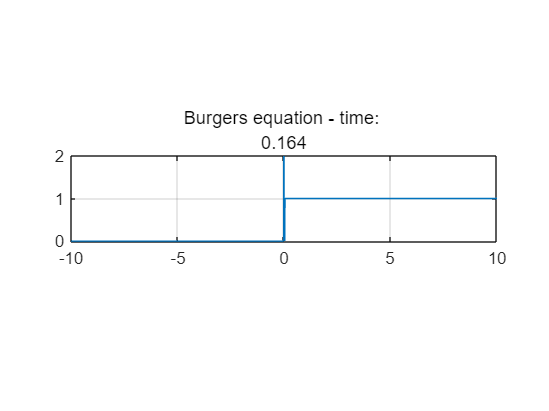

for C = [0.1, 0.5, 1, 5, 10]
    disp("Burgers C = " + C);
    for j = 1:2
        disp("  IVP " + j);
        for dir = [true false]
            disp("  Left " + dir)
            [ts, xs, us] = solve_burgers(pool{j}, -10, 10, 0.5, C, 0.01, dir);
    
            % for k = 1 : length(ts)
            %    if ts()
            % end

            [T, X] = ndgrid(ts, xs);
            
            uf = griddedInterpolant(T, X, us);
            
            ts = 0:0.002:ts(end);
            [T, X] = ndgrid(ts, xs);
            
            us = uf(T, X);
    
            sz = size(us);
            % [Ts, Xs] = meshgrid(ts, xs)
            
            fig = figure(1);
            
            xlim([-10, 10]);
            ylim([0, 0.5]);

            if dir
                s = "left";
            else
                s = "right";
            end
            
            filename = "burgers-" + names(j) + "-" + C + "-" + s + ".gif"; 
    
            imgs = cell(length(ts), 1);
            
            for i = 1 : length(ts)
                plot(xs, us(i, :));
                ylim([0, 2]);
                
                grid on
                pbaspect([5 1 1]);
        
                time = sprintf("%.3f", i * (ts(2) - ts(1)));
                title("Burgers equation - time: ", time);
                % pause(0.1);
            
                frame = getframe(fig);
                imgs{i} = frame2im(frame);
            end
    
            for i = 1 : length(imgs)
                [A, map] = rgb2ind(imgs{i}, 256);
                if i == 1
                    imwrite(A, map, filename, 'gif', 'LoopCount', Inf, 'DelayTime', 0.001);
                else
                    imwrite(A, map, filename, 'gif', 'WriteMode', 'append', 'DelayTime', 0.001);
                end
            end
        end
    end
end

# Functions

## Heat Equation

function [ts, xs, us] = solve_heat(u0f, gamma, L, R, T, C, dx)
    xs = L:dx:R;
    dt = C * dx ^ 2 / (2 * gamma); % CFL: 2 gamma dt <= dx ^ 2
    ts = 0:dt:T;
    
    xn = length(xs);
    tn = length(ts);
    
    us = zeros(tn, xn);
    
    us(1, :) = u0f(xs);
    
    %A = diag(ones(xn, 1) * (1 - 2 * C)) + ...
    %    diag(ones(xn - 1, 1) * C, -1) + diag(ones(xn - 1, 1) * C, 1);
    
    for i = 1 : tn - 1
        % us(i, :) = (A * us(i - 1, :)')';
        for j = 2 : xn - 1
            us(i + 1, j) = us(i, j) + C * (us(i, j - 1) + us(i, j + 1) - 2 * us(i, j));
        end
        us(i + 1, 1) = us(i, 1) + C * (us(i, 2) - us(i, 1));
        us(i + 1, xn) = us(i, xn) + C * (us(i, xn - 1) - us(i, xn));
    end
end

## Burgers Equation

function [ts, xs, us] = solve_burgers(u0f, L, R, T, C, dx, right)
    xs = (L:dx:R)';
    xn = length(xs);
    ts = [0];
    us = zeros(1, xn);
    us(1, :) = u0f(xs);

    function sm = find_sm(xs)
        sm = 0;
        for k = 1 : length(xs) - 1
            sm = max([sm, abs(0.5 * (xs(k) + xs(k + 1))), abs(xs(k)), abs(xs(k + 1))]);
        end
    end

    if right
        s = 1;
    else
        s = -1;
    end
    
    i = 1;
    while true
        sm = find_sm(us(i, :));
        if sm < 10 ^ -18 || sm > 10 ^ 5
            return
        end
        dt = C * dx / sm;
        ts = [ts; ts(end) + dt];

        us(i + 1, :) = zeros(1, xn);
        for j = 2 : xn - 1
            us(i + 1, j) = us(i, j) + s * C * us(i, j) * (us(i, j + 1) - us(i, j - 1)) / (2 * sm);
        end
        us(i + 1, 1) = us(i, 1) + s * C * us(i, 1) * (us(i, 2) - us(i, 1)) / (2 * sm);
        us(i + 1, xn) = us(i, xn) + s * C * us(i, xn) * (us(i, xn) - us(i, xn - 1)) / (2 * sm);

        if (ts(end) > T)
            break;
        end
        i = i + 1;
    end
end